# Training models

*We load the files from the installation-module folder:*

addpath('installation-module');

## Training

### Yolo parameters

In this section, we will explain some of the most important parameters used when training YOLO models. You can find the complete list of parameters in the following link: [Yolo parameters](https://docs.ultralytics.com/usage/cfg/).

**Required Model Parameters**

The following parameters are mandatory when configuring a YOLO training session:

- **configFile **(str)**: **Path to the configuration file (usually in `.yaml` format) that defines the dataset structure and classes. This file should include paths to training, validation, and optional test sets, as well as the list of class names. As an example the file we will use in this tutorial is data.yaml which already contains all the defined structure.

- **baseModel **(str): This parameter specifies which model will be used for training. It allows you to either continue training a previously trained model or start training from a pre-trained YOLO model.You can choose among different YOLO versions, tasks (e.g., object detection, segmentation, classification), and model sizes. For these tutorials, we will use **YOLOv8 for object detection**. The available pre-trained models, ordered from smallest to largest, are: yolov8n.pt, yolov8s.pt, yolov8m.pt, yolov8l.pt, yolov8x.pt. It is recommended to start with smaller models (e.g., `yolov8n.pt` or `yolov8s.pt`) for faster training and inference speed.

- `MaxEpochs ``(int): This parameter `sets the maximum number of epochs for training, where an epoch is one complete pass over all the images in the training dataset. Increasing this value usually improves model performance but also extends training time.

- `ImageSize ``(list[int]): `The size (in pixels) that all images will be resized to before training. Larger sizes may improve accuracy but require more computational resources.

In the following code, we define the values for these required parameters:

configFile = 'data.yaml';
baseModel = 'yolov8s-oiv7.pt';
options.MaxEpochs = 15;
options.ImageSize = [256 256 3];

**Optional Model Parameters**

Here are some of the optional parameters:

- **time** (*float*):Maximum training time in hours. If set, training will stop automatically once this time limit is reached, even if the specified number of epochs is not completed. Useful for time-constrained training.

- **optimizer** (*str*):Specifies the optimizer used during training. Common options include `'SGD'`, `'Adam'`, `'AdamW'`, `'RMSProp'`, or `'auto'` for automatic selection based on the model and task. The optimizer influences learning speed and stability.

- **lr0** (*float*):Initial learning rate controlling how fast the model updates its weights at the start of training. Choosing an appropriate value is important for effective learning.

- **lrf** (*float*):Final learning rate fraction. Defines the fraction of the initial learning rate (`lr0`) that the learning rate will decay to by the end of training, often used with learning rate schedulers.

- **momentum** (*float*):Momentum factor used by optimizers like SGD or Adam, controlling the influence of past gradients on current weight updates, which helps stabilize and speed up training.

- **batch_size **(int/ float)**: ** Batch size can be set in three ways: as an integer (e.g., batch=16) for a fixed batch size; as -1 to automatically use approximately 60% of GPU memory; or as a fraction between 0 and 1 (e.g., batch=0.70) to use that fraction of GPU memory. Batch size affects training speed and memory usage.

- **weight_decay** (*float*):L2 regularization coefficient that penalizes large model weights to reduce overfitting and improve generalization.

- **patience** (*int*):Number of epochs with no improvement in validation metrics after which training is stopped early. Helps prevent overtraining.

In case you do not define a value for these parameters, they already have a default value.

Here we define optional parameters. To set them, use: "parameter_name", value.

Remember that in MATLAB you need to use "..." to continue the command on the next line.

optionalArgs = {
    'time', 1, ...
    'optimizer', 'SGD', ...
    'lr0', 0.01, ...
    'lrf', 0.0001, ...
    'momentum', 0.937, ...
    'batch', 16, ...
    'weight_decay', 0.0005, ...
    'patience', 10 ...
     'save', true, ...
};

**Optional Data augmentation Parameters**

So far, the parameters we have defined were related to the model configuration. Next, we will explain and define the **data augmentation parameters**. You can find the complete list of data augmentation parameters in the following link:  [Data Augmentation Yolo](https://docs.ultralytics.com/usage/cfg/#augmentation-settings).

**Data augmentation is a fundamental technique in machine learning that artificially expands the size and diversity of a training dataset.** Its main purpose is to improve model performance, enhance generalization, and increase robustness by introducing controlled variations into the data.

In the context of YOLO models, data augmentation involves applying small transformations to the original training images to create new, slightly modified versions. These transformations help YOLO models adapt to different conditions such as changes in lighting, scale, or perspective, making them more reliable and effective in real-world scenarios.

The following list describes each augmentation parameter, its role, and its impact:

- **hsv_h **(float): Adjusts the hue of the image by a fraction of the color wheel (0.0 - 1.0). Introduces color variability to help the model generalize under different lighting conditions.

- **hsv_s **(float): Alters the saturation of the image by a fraction (0.0 - 1.0), affecting color intensity. Useful for simulating various environmental conditions.

- **hsv_v **(float): Modifies the brightness (value) of the image by a fraction (0.0 - 1.0), aiding performance under diverse lighting scenarios.

- **degrees **(float): Randomly rotates the image within a range of 0.0 to 180 degrees to improve recognition of objects in different orientations.

- **translate **(float): Shifts the image horizontally and vertically by a fraction of its size (0.0 - 1.0), helping detect partially visible or shifted objects.

- **scale **(float): Scales the image by a gain factor (≥ 0.0), simulating objects at varying distances. Default: 0.5.

- **shear **(float): Shears the image by degrees ranging from -180 to +180, mimicking different viewing angles.

- **perspective** (float): Applies random perspective distortion (0.0 - 0.001) to enhance 3D spatial understanding.

- **flipud **(float): Flips the image upside down with a given probability (0.0 - 1.0), increasing data variety without altering object traits.

- **fliplr **(float): Flips the image left to right with a probability (0.0 - 1.0), useful for learning symmetrical features and boosting dataset diversity. 

- **mosaic** (float): Combines four training images into one with a probability (0.0 - 1.0), simulating complex scenes and object interactions to improve generalization.

Here we define the data augmentation parameters by adding them to the optionalArgs dict:

optionalArgs = [optionalArgs, {'hsv_h', 0.015}];
optionalArgs = [optionalArgs, {'hsv_s', 0.7}];
optionalArgs = [optionalArgs, {'hsv_v', 0.4}];
optionalArgs = [optionalArgs, {'degrees', 0.0}];
optionalArgs = [optionalArgs, {'translate', 0.1}];
optionalArgs = [optionalArgs, {'scale', 0.5}];
optionalArgs = [optionalArgs, {'shear', 0.0}];
optionalArgs = [optionalArgs, {'perspective', 0.0}];
optionalArgs = [optionalArgs, {'flipud', 0.0}];
optionalArgs = [optionalArgs, {'fliplr', 0.5}];
optionalArgs = [optionalArgs, {'mosaic', 1.0}];

**Freezing Layer Parameter for Transfer Learning**

Before moving forward, we need to define one last parameter, which also helps explain why we are using YOLOv8 as our real-time object detection model.

Training a model from scratch for real-time object detection usually requires millions of images, which is both time-consuming and computationally expensive. This challenge can be overcome by using **pre-trained models**. These models have already been trained on large datasets and can be fine-tuned for new tasks with significantly fewer images. This approach is known as **transfer learning**, and it is the technique we will apply here.

**Transfer learning** is particularly effective in computer vision because **convolutional neural networks (CNNs)**, the core architecture behind models like YOLO, learn **hierarchical feature representations**. In the early layers, CNNs capture low-level, general features such as edges, textures, and corners. As the network goes deeper, it progressively learns more complex patterns like shapes and object parts, eventually forming complete object representations in the final layers.

This hierarchical nature makes the initial layers of a pre-trained model excellent **general-purpose feature extractors** that can be reused across different tasks. In transfer learning, these early layers are typically **frozen** (i.e., not updated during training), while the later layers are fine-tuned to adapt to the new dataset. In some cases, the entire network can be fine-tuned using a smaller learning rate to retain previously learned knowledge while adapting to new data.

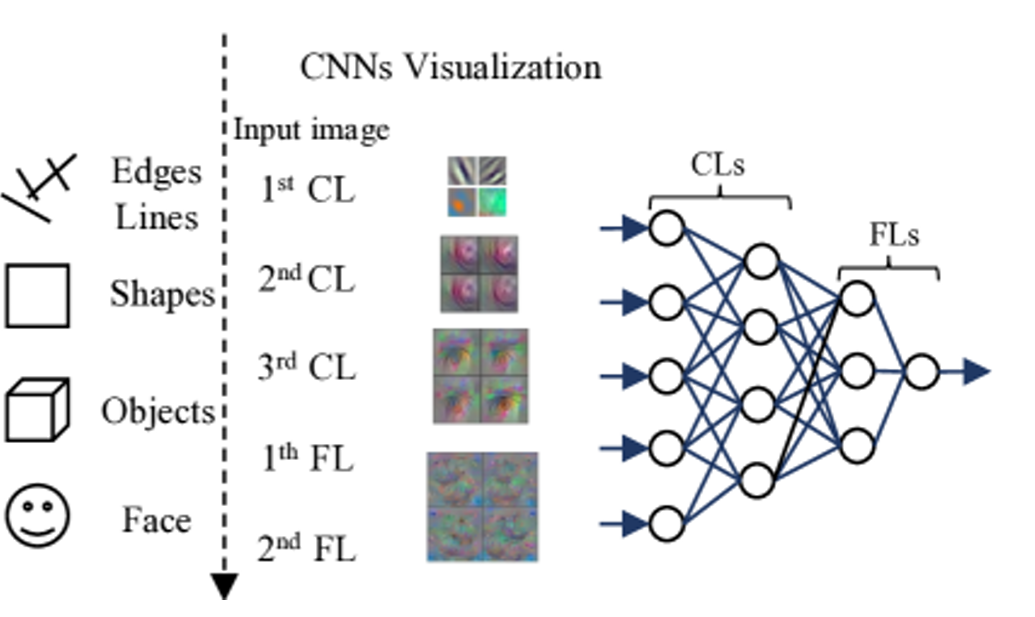

This is why we use **YOLOv8**. It comes pre-trained on large datasets like [**COCO**](https://docs.ultralytics.com/es/datasets/detect/coco/) (for COCO-pretrained models, use as baseModel: `yolov8n.pt`, `yolov8s.pt`, etc.) or [**Open Image V7**](https://docs.ultralytics.com/es/datasets/detect/open-images-v7/#open-images-v7-pretrained-models) (for these models, use as baseModel: `yolov8n-oiv7.pt`, `yolov8s-oiv7.pt`, etc.). Leveraging these models significantly reduces training time and improves accuracy, even with smaller datasets.

To start, the following code allows you to visualize the layers of a YOLO model:

det = yolov8ObjectDetector2('yolov8s');

Pretrained yolov8s network already exists.




% Analyze loaded model
analyzeNetwork(det.Network);

The choice of how many YOLOv8 layers to freeze depends on how similar your target dataset is to the pretrained data. YOLOv8 has 22 freeze-able layers: the first 10 extract generic features (edges, textures, shapes), while later layers specialize in detection. Since our classes (apple, orange, pear) are well represented in COCO and Open Images V7, the domains closely match. This allows us to freeze most layers to keep general features intact and fine-tune only the higher-level layers for our fruits, which speeds training and lowers overfitting risk.

To freeze specific layers during training, we use the `freeze` parameter as follows:

optionalArgs = [optionalArgs, {'freeze', 20}];

yolov8Det = trainYOLOv8ObjectDetector( ...
    configFile, ...
    baseModel, ...
    options, ...
    optionalArgs{:});

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python.exe"
          Library: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python311.dll"
             Home: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python"
           Status: NotLoaded
    ExecutionMode: OutOfProcess



  0%|          | 0.00/21.9M [00:00<?, ?B/s]
  6%|5         | 1.25M/21.9M [00:00<00:01, 12.9MB/s]
 14%|#3        | 3.00M/21.9M [00:00<00:01, 15.6MB/s]
 21%|##1       | 4.62M/21.9M [00:00<00:01, 15.6MB/s]
 29%|##9       | 6.38M/21.9M [00:00<00:00, 16.6MB/s]
 39%|###8      | 8.50M/21.9M [00:00<00:00, 18.0MB/s]
 49%|####9     | 10.8M/21.9M [00:00<00:00, 19.4MB/s]
 59%|#####8    | 12.9M/21.9M [00:00<00:00, 19.3MB/s]
 70%|#######   | 15.4M/21.9M [00:00<00:00, 20.8MB/s]
 81%|########  | 17.8M/21.9M [00:00<00:00, 21.9MB/s]
 92%|#########2| 20.2M/21.9M [00:01<00:00, 21.6MB/s]
100%|##########| 21.9M/21.9M [00:01<00:00, 20.2MB/s]
extra:
    {'SGD'}    {'lr0'}

.........
False
is instance time
is instance batch


is instance patience
is instance degrees
is instance shear
is instance perspective
is instance flipud
is instance mosaic
is instance freeze
New https://pypi.org/project/ultralytics/8.3.169 available 😃 Update with 'pip install -U ultralytics'
Ultralytics YOLOv8.2.66 🚀 Python-3.11.5 torch-2.7.0+cpu CPU (11th Gen Intel Core(TM) i5-1135G7 2.40GHz)
□□engine\trainer: □task=detect, mode=train, model=yolov8s-oiv7.pt, data=data.yaml, epochs=15, time=1, patience=10, batch=16, imgsz=256, save=True, save_period=-1, cache=False, device=None, workers=8, project=None, name=train13, exist_ok=False, pretrained=True, optimizer=SGD, verbose=True, seed=0, deterministic=True, single_cls=False, rect=False, cos_lr=False, close_mosaic=10, resume=False, amp=True, fraction=1.0, profile=False, freeze=20, multi_scale=False, overlap_mask=True, mask_ratio=4, dropout=0.0, val=True, split=val, save_json=False, save_hybrid=False, conf=None, iou=0.7, max_det=300, half=False, dnn=False, plots=True, source=Non

### Load a model

modelPath = fullfile(pwd, 'runs', 'detect', 'train6', 'weights');
configFile = 'data.yaml';

yolov8Det = utils.loadModel(modelPath, configFile);

### Prediction

En esta sección utilizamos el modelo que hemos entrenado previamente para detectar frutas en las siguientes imagenes.

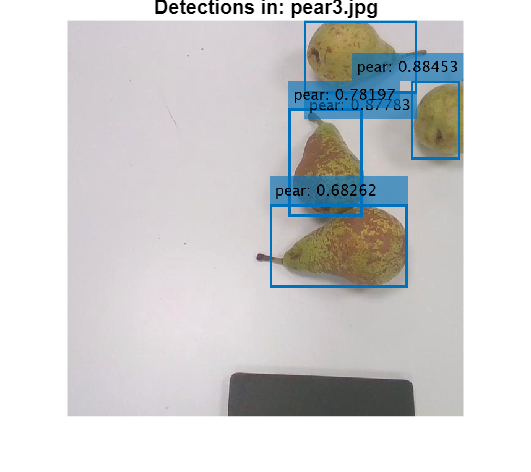

utils.detectAndDisplayImage(yolov8Det, 'pear3.jpg'); 

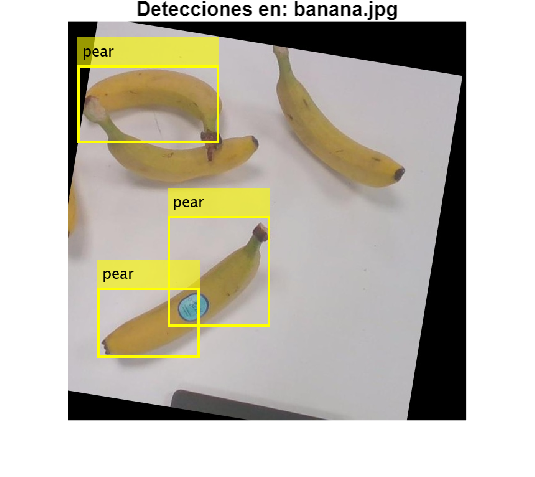

utils.detectAndDisplayImage(yolov8Det, 'banana.jpg');

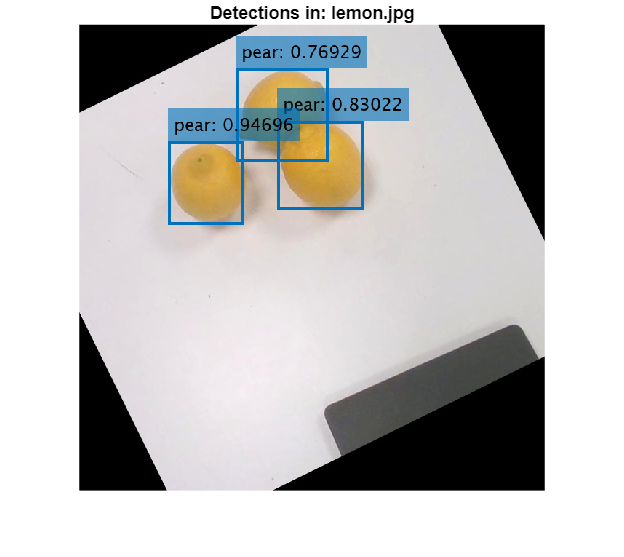

utils.detectAndDisplayImage(yolov8Det, 'lemon.jpg');

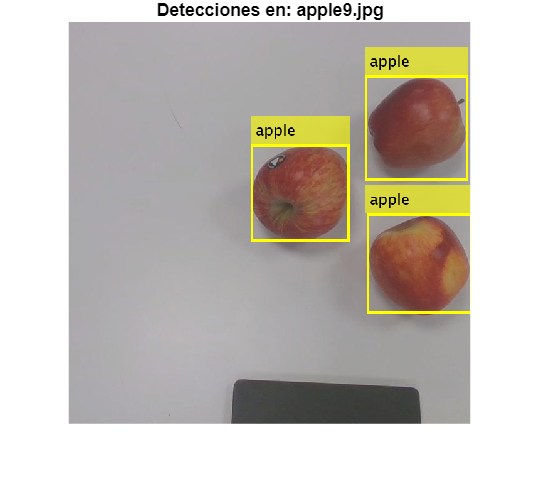

utils.detectAndDisplayImage(yolov8Det, 'apple9.jpg');

scoreee:
    0.7656

.....................


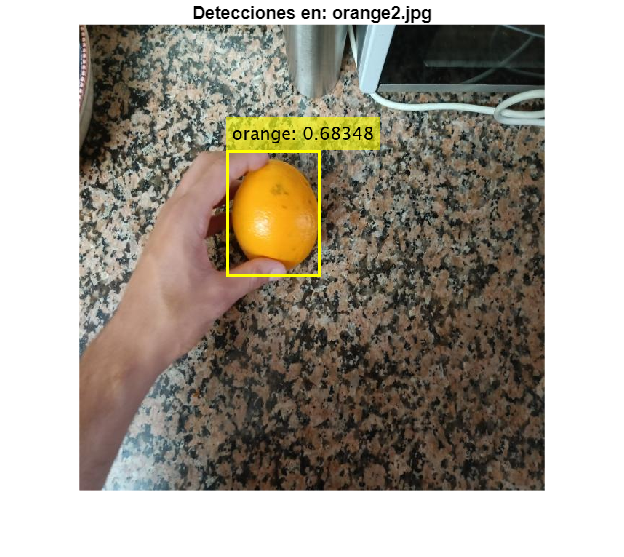

utils.detectAndDisplayImage(yolov8Det, 'orange3.jpg');

Hemos podido ver que los resultados son correctos

modelPath = fullfile(pwd, 'weight');
baseModel = 'yolov8s.pt';
options.ImageSize = [512 512 3];
configFile = 'data.yaml'; 

yolov8Det = utils.loadModel(modelPath, baseModel, options, configFile);

Error using nnet.internal.cnn.onnx.importONNXNetwork>iValidateInputs (line 179)
File not found: 'C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weight\best.onnx'.

Error in nnet.internal.cnn.onnx.importONNXNetwork


utils.detectAndDisplayImage(yolov8Det, 'test3.jpg');

### Continue a train

En el caso de que la ejecución se hubiese parado por cualquier motivo a mitad del entrenamiento, se puede usar resume:

model_folder = fullfile(pwd, 'runs', 'detect', 'train3', 'weights', 'best.pt');
yolov8Det = trainYOLOv8ObjectDetector( ...
    configFile, ...
    model_folder, ...
    options, ...
    'resume', true ...                    
);

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python\python.exe"
          Library: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python\python311.dll"
             Home: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


New https://pypi.org/project/ultralytics/8.3.168 available 😃 Update with 'pip install -U ultralytics'
Ultralytics YOLOv8.2.66 🚀 Python-3.11.5 torch-2.7.0+cpu CPU (11th Gen Intel Core(TM) i5-1135G7 2.40GHz)
□□engine\trainer: □task=detect, mode=train, model=C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs\detect\train3\weights\best.pt, data=data.yaml, epochs=2, time=None, patience=100, batch=16, imgsz=256, save=True, save_period=-1, cache=False, device=None, workers=0, project=None, name=train3, exist_ok=False, pretrained=True, optimizer=auto, verbose=True, seed=0, deterministic=True, single_cls=False, rect=False, cos_lr=False, close_mosaic=10, resume=C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs\detect\train3\weights\best.pt, amp=True, fraction=1.0, profile=False, freeze=None, multi_scale=False, overlap_mask=True, mask_ratio=4, dropout=0.0, val=True, split=v

  4                  -1  2     49664  ultralytics.nn.modules.block.C2f             [64, 64, 2, True]             
  5                  -1  1     73984  ultralytics.nn.modules.conv.Conv             [64, 128, 3, 2]               
  6                  -1  2    197632  ultralytics.nn.modules.block.C2f             [128, 128, 2, True]           
  7                  -1  1    295424  ultralytics.nn.modules.conv.Conv             [128, 256, 3, 2]              
  8                  -1  1    460288  ultralytics.nn.modules.block.C2f             [256, 256, 1, True]           
  9                  -1  1    164608  ultralytics.nn.modules.block.SPPF            [256, 256, 5]                 
 10                  -1  1         0  torch.nn.modules.upsampling.Upsample         [None, 2, 'nearest']          
 11             [-1, 6]  1         0  ultralytics.nn.modules.conv.Concat           [1]                           
 12                  -1  1    148224  ultralytics.nn.modules.block.C2f             [384,

Utilizando resume se loads the weights from the last saved model and also restores the optimizer state, [learning rate](https://www.ultralytics.com/glossary/learning-rate) scheduler, and the epoch number. This allows you to continue the training process seamlessly from where it was left off.

Para más información: [Resume Training](https://docs.ultralytics.com/modes/train/#resuming-interrupted-trainings).

### Retrain a model

Por otro lado, se podría volver a entrenar un modelo ya entrenado, para esto, en vez de cargar un modelo base  como `yolov8n.pt o` `yolov8s.pt, hay que cargar un modelo ya entrenado. La diferencia con resume es que en este caso el optimizer state, learning rate y epoch se resetean.`

model_folder = fullfile(pwd, 'runs', 'detect', 'train3', 'weights', 'best.pt');
yolov8Det = trainYOLOv8ObjectDetector( ...
    configFile, ...
    baseModel, ...
    options, ...
    'lr0', 0.01, ...              
    'weight_decay', 0.0005, ...   
    'patience', 10 ...           
);